# **Exploring brain-behaviour relationships in the tbfMRI choir-singing dataset**

The results from the behavioural analyses are:

- Communication index 

- Responsive Speech

- SIS participation and role function subscale

- Caregiver burden index (not included in this analisis)

clear all
% Specify directories and patients
data_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/post-pre_diff_images/TU/';
mask_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/'

mask_path = '/Volumes/LASA/Aphasia_project/tb-fMRI/results/'

output_path='/Volumes/LASA/Aphasia_project/tb-fMRI/results/behaviour/cluster/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/tbfMRI_LASA_current_code/notebooks/behaviour'; %add code path

First, we will extract the values from the significant behavioural variables for each patient:

% Import behavioural data and extract variables for the fMRI sample (N=28)
Data = fileread(fullfile(output_path,'LASA_questionnaires_CVA_TBI_beh_fMRI.csv'));
Data = strrep(Data, ',', '.');
FID = fopen('LASA_questionnaires_CVA_TBI_beh_fMRI_fixed.csv', 'w');
fwrite(FID, Data, 'char');
fclose(FID);
importfile_behaviour('LASA_questionnaires_CVA_TBI_beh_fMRI_fixed.csv');
Comm_Idx_int_all=ans.Communication_index_INT;
Resp_Speech_Idx_int_all=ans.Change_WAB_naming_repetition_intervention;
%SIS_part_fun_int_all=;
ID_BIDS_all=ans.ID_num;

Second, we will extract the average intensity values from the clusters with significant results in the paired T-test and flexible factorial for the corresponding contrasts (peak value of the cluster below):

- Paired T, Tydyy-Uulaa Singing along vs rest: PoG R (48,-16,39)

- Paired T, Tydyy-Uulaa Singing along vs singing from memory: PreG R/IFG R (58,4,29)

- Flexible ABvsBA&TP2vsTP1, Tydyy-Uulaa Singing along vs rest: STG R (48,-12,15)

% Save peak value and contrast name to variable
peak1=[48,-16,39];% paired T singavsrest MNI coord in mm from the cluster
peak2=[58,4,29]; %paired T singavssingm MNI coord in mm from the cluster
peak3=[48,-12,15]; %flexible singavsrest MNI coord in mm from the cluster
contrast1='Sing_along>Baseline';
contrast2='Sing_along>Sing_mem';
mask1name='singavsrest_T_clus48-1639.nii';
mask2name='singvsrest_flex_clus48-12-5.nii';
mask3name='singavssingm_T_clus58429.nii';



## Contrast 1: Paired T test Tydyy-Uulaa Sing along vs Rest

x =     6.4497
    0.2347
   -1.7467
   12.5213
    6.0727
    1.9899
    8.2410
    4.4995
    8.7250
    6.0882


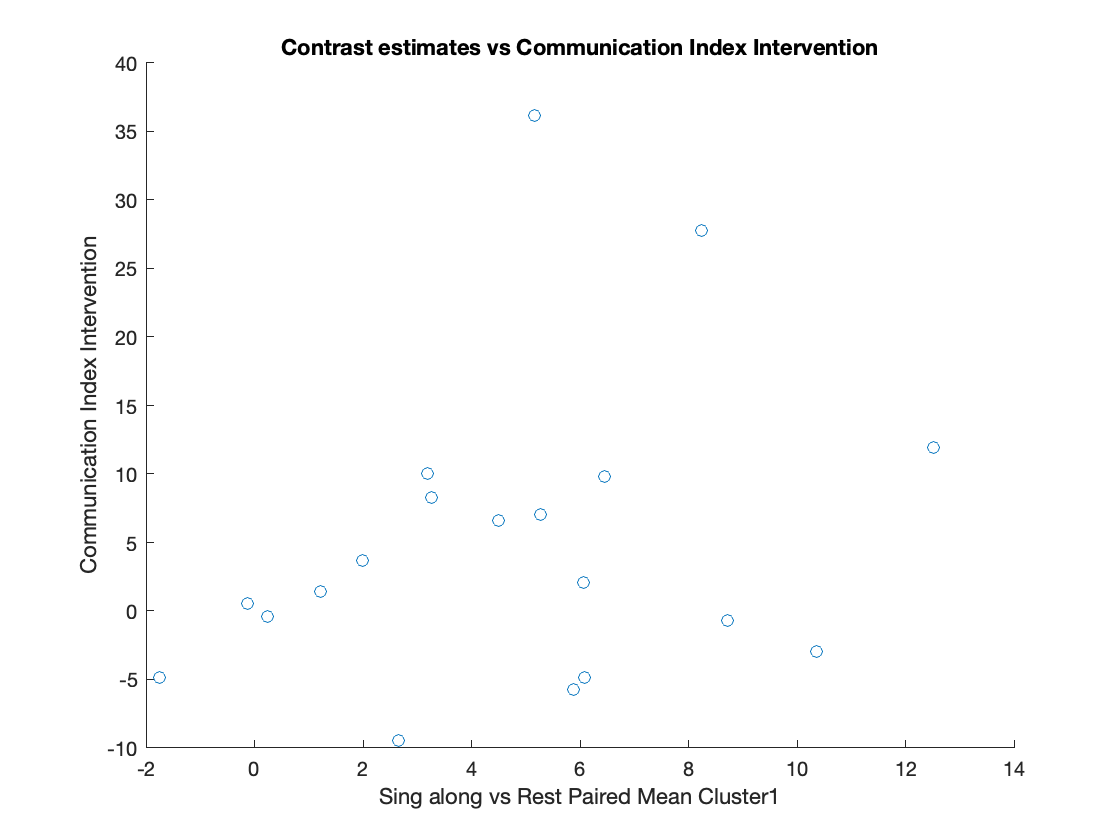

% Get the image filenames
filenames_contrast1= dir(fullfile(data_path,contrast1));
filenames_contrast1(ismember({filenames_contrast1.name},{'.','..'}))=[];

% Get L2 mask indices from FWEc cluster
    mask1=spm_vol(fullfile(mask_path,'paired T test/singa_vs_rest_TU_Age_TIV_wo_motion_outliers_wo_14/',mask1name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask1);
    mask1_idx=find(M~=0);
    mask1_int=mean(M(mask1_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask1_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask1{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask1{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask1(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast1=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast1=Resp_Speech_Idx_int_all(iall,:);

% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(Comm_Idx_int_pat_contrast1(:,1)));
    Comm_Idx_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_comm=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_comm(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=Comm_Idx_int_pat_contrast1;
        if exist('pa_int_mask1_comm')==1
            x=pa_int_mask1_comm;
        else
            x=cell2mat(pa_int_mask1(:,2))
        end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_Communication_Index_mean_cluster' num2str(p) '.jpg'])
        save('Communication_Index_int_singavsrest_mean_cluster','x','y')
        CI_singavsrest_T=table(x,y);
        writetable(CI_singavsrest_T, 'CI_singavsrest_T_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson')

rho_mask1 = 0.2713

pval_mask1 = 0.2613

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman')

rho_mask1 = 0.2456

pval_mask1 = 0.3094

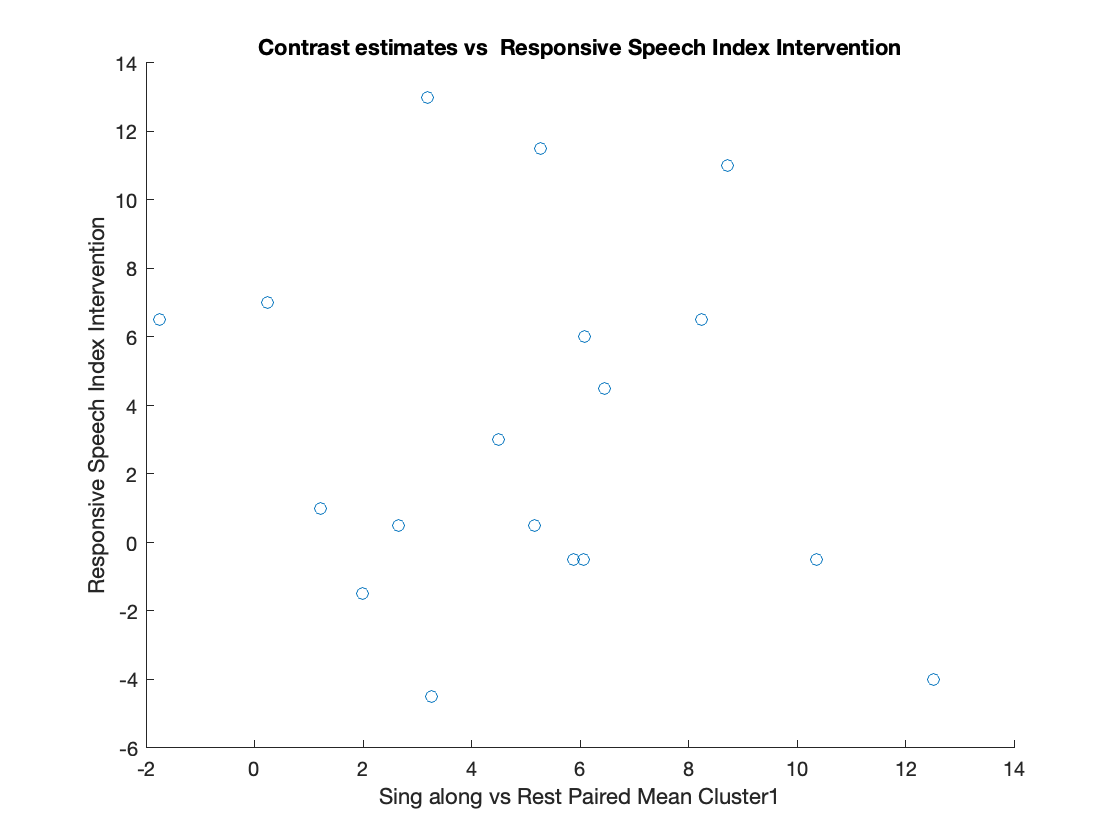

clear x y

% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast1(:,1)))~=0
    NAN_Index_contrast1=find(isnan(Resp_Speech_Idx_int_pat_contrast1(:,1)));
    Resp_Speech_Idx_int_pat_contrast1(NAN_Index_contrast1,:)=[];
    pa_int_mask1_resp=cell2mat(pa_int_mask1(:,2));
    pa_int_mask1_resp(NAN_Index_contrast1,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask1,1)
        y=Resp_Speech_Idx_int_pat_contrast1;
           if exist('pa_int_mask1_resp')==1
            x=pa_int_mask1_resp;
        else
            x=cell2mat(pa_int_mask1(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsRest_Responsive_Speech_Index_mean_cluster' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavsrest_mean_cluster','x','y')
        RSI_singavsrest_T=table(x,y);
        writetable(RSI_singavsrest_T, 'RSI_singavsrest_T_mean_cluster.xlsx')
end


% correlation
[rho_mask1,pval_mask1] = corr(x,y,'Type','Pearson')

rho_mask1 = -0.1587

pval_mask1 = 0.5293

[rho_mask1,pval_mask1] = corr(x,y,'Type','Spearman')

rho_mask1 = -0.1600

pval_mask1 = 0.5247

clear x y M mean_int Y V


## Contrast 1: Flexible AB>BAxTP2>TP1 Tydyy-Uulaa Sing along vs Rest

% Get L2 mask indices from FWEc cluster
    mask2=spm_vol(fullfile(mask_path,'flexible factorial/singa_vs_rest_TU_2by3_Age_wo_motion_outliers_wo_14/',mask2name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask2);
    mask2_idx=find(M~=0);
    mask2_int=mean(M(mask2_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask2_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask2{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask2{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask2(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast1f=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast1f=Resp_Speech_Idx_int_all(iall,:)

Resp_Speech_Idx_int_pat_contrast1f =     4.5000
    7.0000
    6.5000
   -4.0000
   -0.5000
   -1.5000
    6.5000
    3.0000
   11.0000
    6.0000


x =     6.7725
   -5.9457
    0.5117
    5.2451
   -0.7152
    7.9908
    7.2583
    1.1340
    5.4629
    2.4578


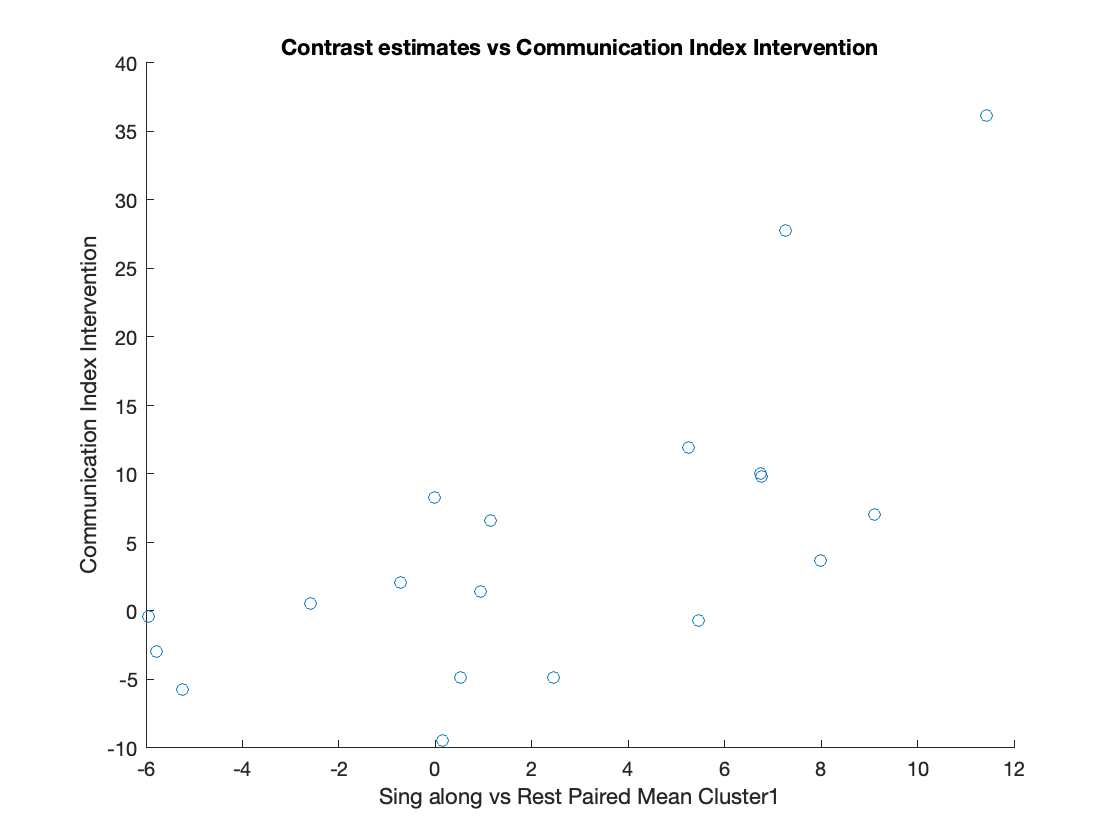


% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(Comm_Idx_int_pat_contrast1f(:,1)));
    Comm_Idx_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_mask2_comm=cell2mat(pa_int_mask2(:,2));
    pa_int_mask2_comm(NAN_Index_contrast1f,:)=[];
end
    
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=Comm_Idx_int_pat_contrast1f;
           if exist('pa_int_mask2_comm')==1
            x=pa_int_mask2_comm;
        else
            x=cell2mat(pa_int_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_Communication_Index_mean_cluster' num2str(p) '.jpg'])
        save('Communication_Index_int_singavsrest_flex_mean_cluster','x','y')
        CI_singavsrest_F=table(x,y);
        writetable(CI_singavsrest_F, 'CI_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson')

rho_mask2 = 0.6768

pval_mask2 = 0.0015

[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.6421

pval_mask2 = 0.0038

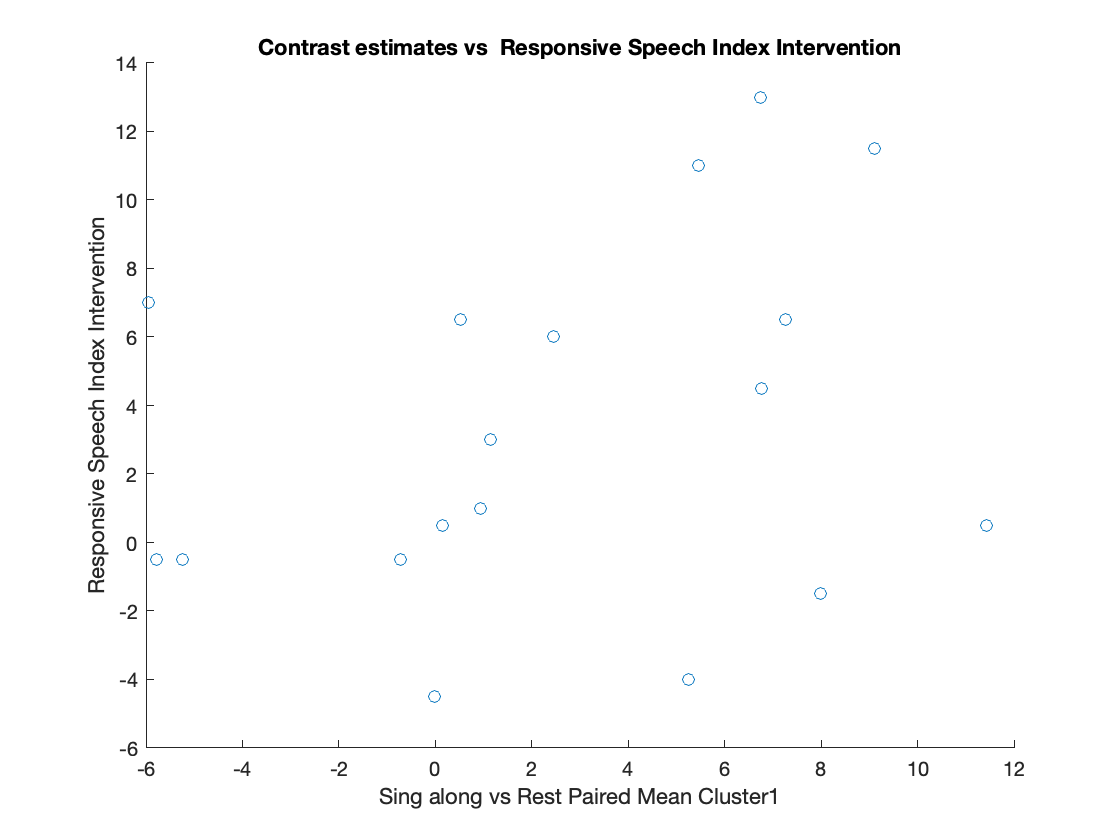

clear x y M mean_int Y V

% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast1f(:,1)))~=0
    NAN_Index_contrast1f=find(isnan(Resp_Speech_Idx_int_pat_contrast1f(:,1)));
    Resp_Speech_Idx_int_pat_contrast1f(NAN_Index_contrast1f,:)=[];
    pa_int_mask2_resp=cell2mat(pa_int_mask2(:,2));
    pa_int_mask2_resp(NAN_Index_contrast1f,:)=[];
end

%% Plot Intensity against behaviour for the cluster mean
for p=1:size(1,1)
        y=Resp_Speech_Idx_int_pat_contrast1f;
           if exist('pa_int_mask2_resp')==1
            x=pa_int_mask2_resp;
        else
            x=cell2mat(pa_int_mask2(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Rest Paired Mean Cluster' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_flex_SingavsRest_Responsive_Speech_Index_mean_cluster' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavsrest_flex_mean_cluster','x','y')
        RSI_singavsrest_F=table(x,y);
        writetable(RSI_singavsrest_F, 'RSI_singavsrest_F_mean_cluster.xlsx')
end


% correlation
[rho_mask2,pval_mask2] = corr(x,y,'Type','Pearson')

rho_mask2 = 0.2872

pval_mask2 = 0.2478

[rho_mask2,pval_mask2] = corr(x,y,'Type','Spearman')

rho_mask2 = 0.2632

pval_mask2 = 0.2902

clear x y M mean_int Y V


## Contrast 2: Paired T test Tydyy-Uulaa Sing along vs Sing mem

x =     0.2586
    2.8498
   -2.6356
    6.3710
   -7.8924
    5.9893
   12.6216
    6.9072
    3.0221
    8.9099


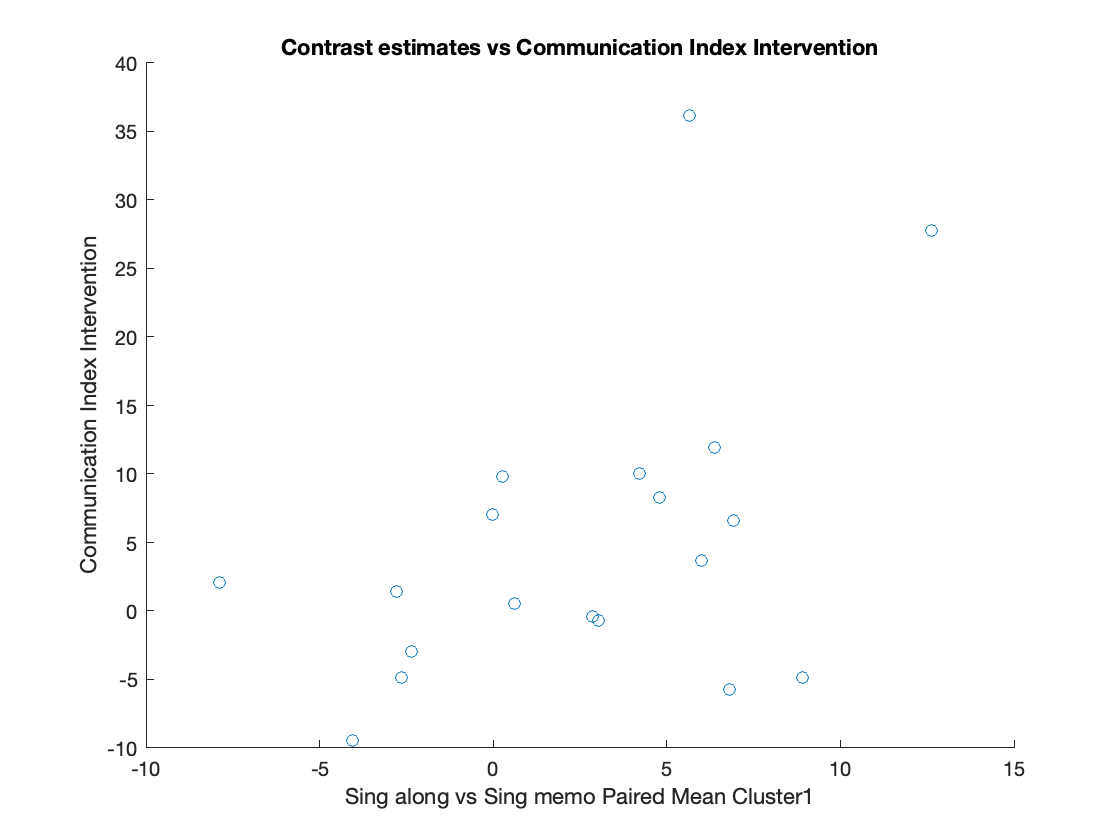

% Get the image filenames
filenames_contrast2= dir(fullfile(data_path,contrast2));
filenames_contrast2(ismember({filenames_contrast2.name},{'.','..'}))=[];

% Get L2 mask indices from FWEc cluster
    mask3=spm_vol(fullfile(mask_path,'paired T test/singa_vs_singm_TU_Age_TIV_wo_motion_outliers_wo_14',mask3name)); %created manually with SPM L2 results
    [M, XYZmm]=spm_read_vols(mask3);
    mask3_idx=find(M~=0);
    mask3_int=mean(M(mask3_idx));%internal check
    
% Get mean cluster intensity for all patients
for i=1:size(filenames_contrast1,1)
    V=spm_vol(fullfile(data_path,contrast1,filenames_contrast1(i).name)); % Get image information
    [Y, XYZmm]=spm_read_vols(V);
    mean_int=mean(Y(mask3_idx));
    [~,name,ext] =fileparts(filenames_contrast1(i).name);
    pa_int_mask3{i,1}=str2num(name(end-1:end)); %Save the patient ID in BIDS
    pa_int_mask3{i,2}=mean_int;% Save mean intensity value for the cluster from all patients
end

%% Get behavioural values from the patients with existing images
ID_BIDS_pat=cell2mat(pa_int_mask3(:,1));
[idx_pat,iall,i] = intersect(ID_BIDS_all,ID_BIDS_pat);
Comm_Idx_int_pat_contrast2=Comm_Idx_int_all(iall,:);
Resp_Speech_Idx_int_pat_contrast2=Resp_Speech_Idx_int_all(iall,:);

% Remove patients with NaN values in behaviour
if sum(isnan(Comm_Idx_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(Comm_Idx_int_pat_contrast2(:,1)));
    Comm_Idx_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_mask3_comm=cell2mat(pa_int_mask3(:,2));
    pa_int_mask3_comm(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask3,1)
        y=Comm_Idx_int_pat_contrast2;
           if exist('pa_int_mask3_comm')==1
            x=pa_int_mask3_comm;
        else
            x=cell2mat(pa_int_mask3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs Communication Index Intervention'), xlabel(['Sing along vs Sing memo Paired Mean Cluster' num2str(p)]), ylabel ('Communication Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingmemo_Communication_Index_mean_cluster_' num2str(p) '.jpg'])
        save('Communication_Index_int_singavssingm_mean_cluster','x','y')
        CI_singavssingm_T=table(x,y);
        writetable(CI_singavssingm_T, 'CI_singavssingm_T_mean_cluster.xlsx')
end


% Pearson correlation
[rho_mask3,pval_mask3] = corr(x,y,'Type','Pearson')

rho_mask3 = 0.4674

pval_mask3 = 0.0436

[rho_mask3,pval_mask3] = corr(x,y,'Type','Spearman')

rho_mask3 = 0.3439

pval_mask3 = 0.1496

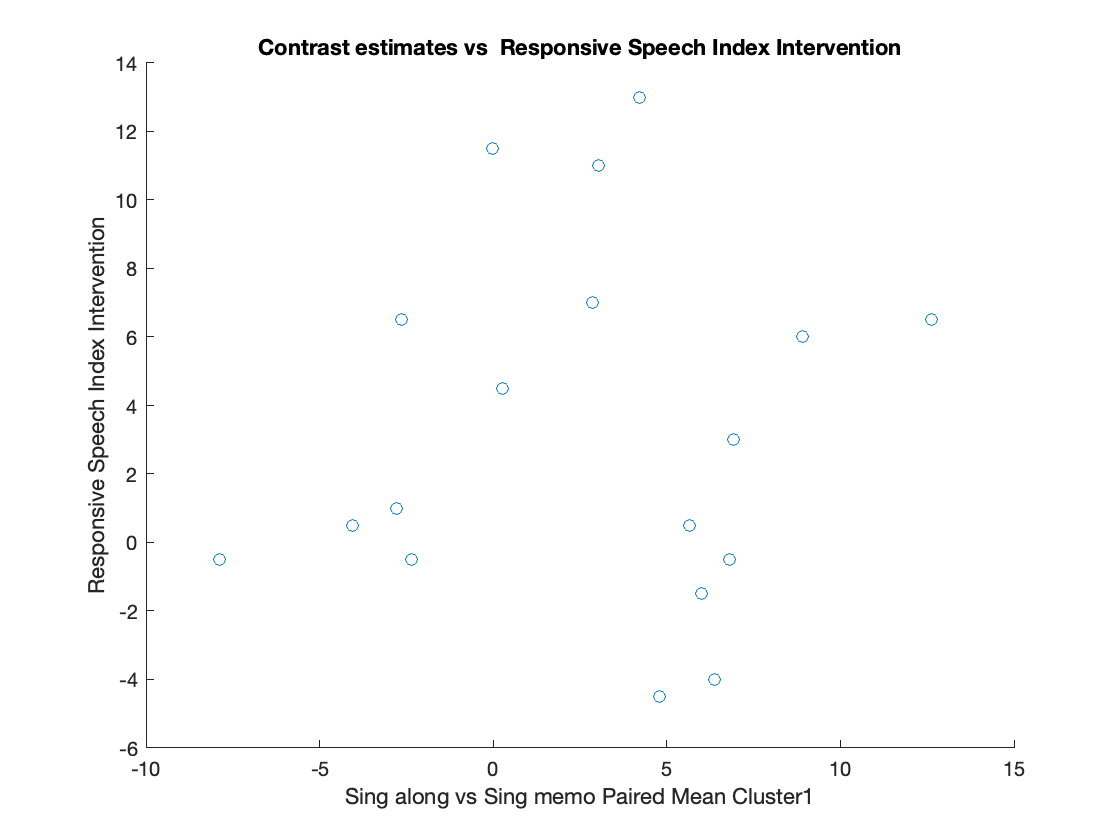


clear x y M mean_int Y V

% Remove patients with NaN values in behaviour
if sum(isnan(Resp_Speech_Idx_int_pat_contrast2(:,1)))~=0
    NAN_Index_contrast2=find(isnan(Resp_Speech_Idx_int_pat_contrast2(:,1)));
    Resp_Speech_Idx_int_pat_contrast2(NAN_Index_contrast2,:)=[];
    pa_int_mask3_resp=cell2mat(pa_int_mask3(:,2));
    pa_int_mask3_resp(NAN_Index_contrast2,:)=[];
end
%% Plot Intensity against behaviour for the cluster mean
for p=1:size(mask2,1)
        y=Resp_Speech_Idx_int_pat_contrast2;
           if exist('pa_int_mask3_resp')==1
            x=pa_int_mask3_resp;
        else
            x=cell2mat(pa_int_mask3(:,2))
           end
        figure
        scatter(x,y)
        title ('Contrast estimates vs  Responsive Speech Index Intervention'), xlabel(['Sing along vs Sing memo Paired Mean Cluster' num2str(p)]), ylabel ('Responsive Speech Index Intervention')
        cd(output_path)
        saveas(gcf,['scatter_betas_PairedT_SingavsSingmemo_Responsive_Speech_Index_mean_cluster_' num2str(p) '.jpg'])
        save('Responsive_Speech_Index_int_singavssingmemo_mean_cluster','x','y')
        RSI_singavssingm_T=table(x,y);
        writetable(RSI_singavssingm_T, 'RSI_singavssingm_T_mean_cluster.xlsx')
end


% correlation
[rho_mask3,pval_mask3] = corr(x,y,'Type','Pearson')

rho_mask3 = 0.0660

pval_mask3 = 0.7948

[rho_mask3,pval_mask3] = corr(x,y,'Type','Spearman')

rho_mask3 = -0.0485

pval_mask3 = 0.8499


clear x y M mean_int Y V
